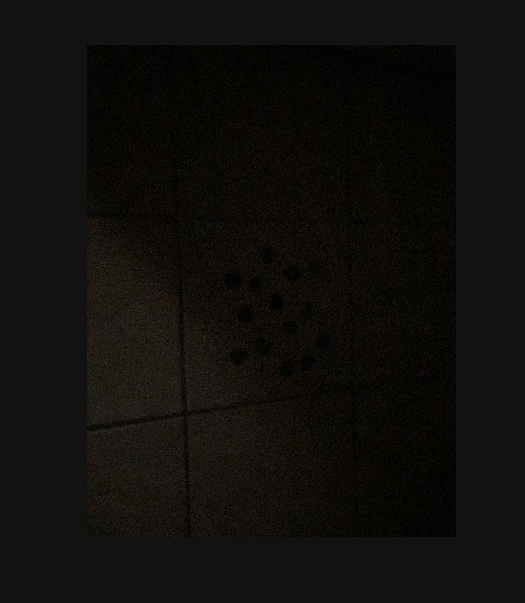

img = imread("picks.jpg");
imshow(img);

imgHSV = rgb2hsv(img);
val = imgHSV(:, :, 3);

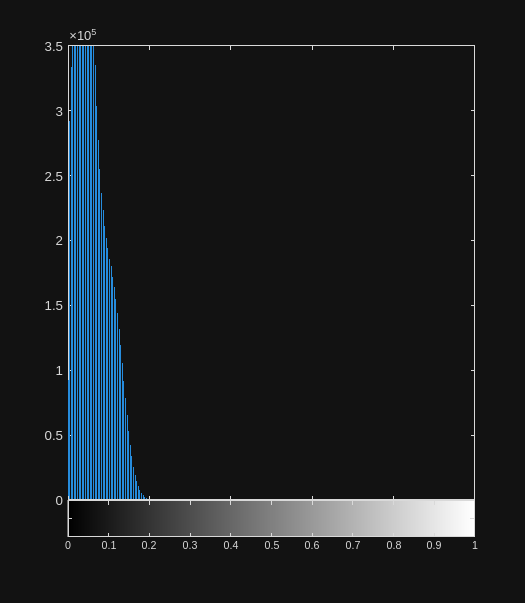

imhist(val);

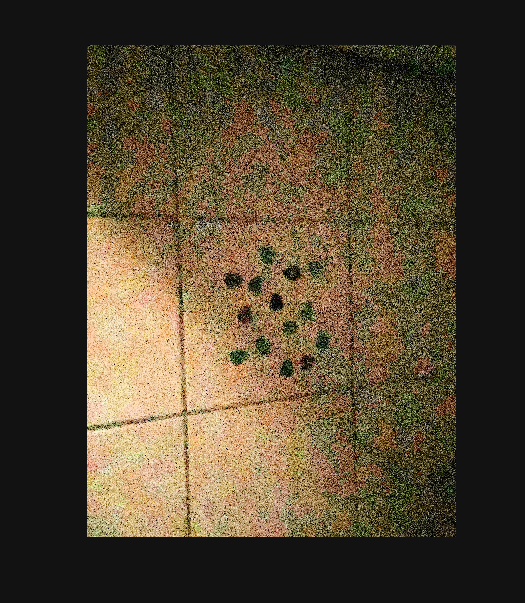

val0 = val;
val0 = histeq(val0);
imgEq = imgHSV;
imgEq(:, :, 3) = val0;
imgEq = im2uint8(hsv2rgb(imgEq));
imshow(imgEq);